clear; clc; close all;

% 文件路径（请修改为您的实际文件路径）
filename = '../../../output/debug.log';

% 初始化存储向量
cost_reuse = [];
cost_nonreuse = [];

% 读取文件
try
    % 打开文件
    fid = fopen(filename, 'r');
    if fid == -1
        error('无法打开文件: %s', filename);
    end
    
    % 逐行读取文件
    line_count = 0;
    while ~feof(fid)
        line = fgetl(fid);
        line_count = line_count + 1;
        
        % 检查行是否包含目标信息
        if contains(line, 'cost_reuse:') && contains(line, 'cost_nonreuse:')
            try
                % 方法1: 使用正则表达式提取数值
                % 匹配格式: cost_reuse: <value1>, cost_nonreuse: <value2>
                pattern = 'cost_reuse:\s*([\d\.]+),\s*cost_nonreuse:\s*([\d\.]+)';
                tokens = regexp(line, pattern, 'tokens');
                
                if ~isempty(tokens)
                    value1 = str2double(tokens{1}{1});
                    value2 = str2double(tokens{1}{2});
                    
                    % 检查提取的数值是否有效
                    if ~isnan(value1) && ~isnan(value2)
                        cost_reuse = [cost_reuse; value1];
                        cost_nonreuse = [cost_nonreuse; value2];
                    else
                        fprintf('警告: 第%d行数值转换失败: %s\n', line_count, line);
                    end
                else
                    % 方法2: 如果正则表达式失败，尝试其他方法
                    fprintf('尝试备用方法解析第%d行...\n', line_count);
                    
                    % 分割字符串
                    parts = strsplit(line, ',');
                    if length(parts) >= 2
                        % 提取第一个数值
                        reuse_part = parts{contains(parts, 'cost_reuse:')};
                        reuse_num = regexp(reuse_part, '[\d\.]+', 'match');
                        
                        % 提取第二个数值
                        nonreuse_part = parts{contains(parts, 'cost_nonreuse:')};
                        nonreuse_num = regexp(nonreuse_part, '[\d\.]+', 'match');
                        
                        if ~isempty(reuse_num) && ~isempty(nonreuse_num)
                            value1 = str2double(reuse_num{1});
                            value2 = str2double(nonreuse_num{1});
                            
                            if ~isnan(value1) && ~isnan(value2)
                                cost_reuse = [cost_reuse; value1];
                                cost_nonreuse = [cost_nonreuse; value2];
                            end
                        end
                    end
                end
                
            catch ME
                fprintf('解析第%d行时出错: %s\n', line_count, line);
                fprintf('错误信息: %s\n', ME.message);
            end
        end
    end
    
    % 关闭文件
    fclose(fid);
    
    fprintf('成功处理 %d 行数据\n', line_count);
    fprintf('提取到 %d 个 cost_reuse 值和 %d 个 cost_nonreuse 值\n', ...
            length(cost_reuse), length(cost_nonreuse));
    
catch ME
    fprintf('文件读取错误: %s\n', ME.message);
    return;
end

成功处理 390954 行数据


提取到 12 个 cost_reuse 值和 12 个 cost_nonreuse 值


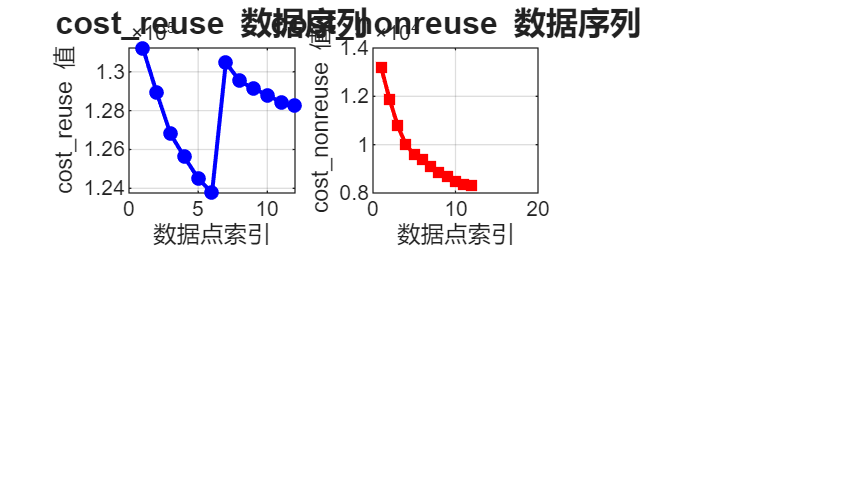


% 检查是否成功提取数据
if isempty(cost_reuse) || isempty(cost_nonreuse)
    fprintf('未找到有效数据，请检查文件格式\n');
    return;
end

%% 数据可视化
% 设置图形
figure('Position', [100, 100, 1400, 800]);

% 子图1: cost_reuse 可视化
subplot(2, 3, 1);
plot(cost_reuse, 'b-o', 'LineWidth', 1.5, 'MarkerSize', 4, 'MarkerFaceColor', 'b');
title('cost\_reuse 数据序列', 'FontSize', 12, 'FontWeight', 'bold');
xlabel('数据点索引');
ylabel('cost\_reuse 值');
% xlim([0, 12]);
grid on;

% 子图2: cost_nonreuse 可视化
subplot(2, 3, 2);
plot(cost_nonreuse, 'r-s', 'LineWidth', 1.5, 'MarkerSize', 4, 'MarkerFaceColor', 'r');
title('cost\_nonreuse 数据序列', 'FontSize', 12, 'FontWeight', 'bold');
xlabel('数据点索引');
ylabel('cost\_nonreuse 值');
xlim([0, 20]);
grid on;